clear All
clc

## Importing variety of time series

Importing S&P 500 Daily time series

spx_short = readmatrix('../data/spx_daily_11-21.csv');
spx_short = fliplr(transpose(spx_short(:,2)));
idx = 1:length(spx_short);
disp("S&P 500 Daily: (length: "+length(spx_short)+")")
plot(idx,spx_short)

Importing S&P 500 all time Monthly time series over 200 years

spx_long = readmatrix('../data/spx_monthly_alltime.csv');
spx_long = transpose(spx_long(:,2));
idx = 1:length(spx_long);
disp("S&P 500 all time: (length: "+length(spx_long)+")")
plot(idx,spx_long)

Importing minimum temperature dataset

min_daily_temp = readmatrix('../data/daily-minimum-temperatures-in-melbourne.csv');
min_daily_temp = transpose(min_daily_temp(:,2));
idx = 1:length(min_daily_temp);
disp("Minimum temperature dataset: (length: "+length(min_daily_temp)+")")
plot(idx,min_daily_temp)

Importing german GDP

bip_de = readmatrix('../data/bip_de_preisbereinigt.csv');
bip_de = transpose(bip_de(:,2));
idx = 1:length(bip_de);
disp("German GDP: (length: "+length(bip_de)+")")
plot(idx,bip_de)

Importing german DAX 2021

dax = readmatrix('../data/dax.csv');
dax = transpose(dax(:,2));
idx = 1:length(dax);
disp("DAX 2021: (length: "+length(dax)+")")
plot(idx,dax)

Importing german DAX alltime

dax_alltime = readmatrix('../data/dax_alltime.csv');
dax_alltime = transpose(dax_alltime(:,2));
for i=2:length(dax_alltime)
    if isnan(dax_alltime(i))
        dax_alltime(i) = dax_alltime(i-1);
    end
end
idx = 1:length(dax_alltime);
disp("DAX all time: (length: "+length(dax_alltime)+")")
plot(idx,dax_alltime)

Importing Bitcoin alltime

bitcoin_alltime = readmatrix('../data/bitcoin_alltime.csv');
bitcoin_alltime = transpose(bitcoin_alltime(:,2));
for i=2:length(bitcoin_alltime)
    if isnan(bitcoin_alltime(i))
        bitcoin_alltime(i) = bitcoin_alltime(i-1);
    end
end
idx = 1:length(bitcoin_alltime);
disp("Bitcoin all time: (length: "+length(bitcoin_alltime)+")")
plot(idx,bitcoin_alltime)

Importing hydraulic pressure Data Set

hydraulic = readmatrix('../data/PS1.csv');
hydraulic = transpose(hydraulic(2:length(hydraulic),2));
for i=2:length(hydraulic)
    if isnan(hydraulic(i))
        hydraulic(i) = hydraulic(i-1);
    end
end
idx = 1:length(hydraulic);
disp("Hydraulic pressure data set: (length: "+length(hydraulic)+")")
plot(idx,hydraulic)

Importing Beijing O3 in air concentration (quality)

quality = readmatrix('../data/PRSA_Data_Dingling_20130301-20170228.csv');
quality = transpose(quality(:,11));
for i=2:length(quality)
    if isnan(quality(i))
        quality(i) = quality(i-1);
    end
end
idx = 1:length(quality);
disp("Beijing O3 in air concentration : (length: "+length(quality)+")")
plot(idx,quality)

## Setting hyper parameters for experiment run

% number of iterations of meaningfulness calculation to average over.
n = 10;
% size of cluster set to be calculated for within/between set cluster distance.
r = 3;

ks = [3 5 7 11];
ws = [8 16 32];

normMethods = ["none" "zscore" "norm" "scale" "range" "medianiqr"];
distMetrics = ["eukl" ""];
clusterAlgos = ["kmeans" "agglo" "gmm"];
% timeSeries = [spx_short spx_long min_daily_temp dax dax_alltime bitcoin_alltime quality hydraulic]

currentNorm = normMethods(5);
% used clustering algorithm
currentClusterAlgo = clusterAlgos(1);

% used distance metric
currentDistMetric = distMetrics(1);

% reduces de sampling size of the random sampled subsequences that are used for whole clustering
% if false the random samples matrix has the same height as the sts matrix
reducedSamplingSize = true;
dimRed = true;

% if hyperparameters should be same among all cluster algorithms
unify = true;

% used time series
currentTs = dax;
% Instead of a random walk we could also pass any opposing time series
%opposingTs = spx_long;
opposingTs = createRandomWalk(currentTs);

## Finally calculate Meaningfulness

disp('Experiment settings:')
disp('')
fprintf("n:                                           %d",n)
fprintf('r:                                           %d',r)
disp('Normalizer:                                  '+currentNorm)
disp('Distance metric:                             '+currentDistMetric)
disp('Clustering algorithm:                        '+currentClusterAlgo)
fprintf('Reduced sampling size for whole clustering:  %d',reducedSamplingSize)
fprintf('PCA:                                         %d',dimRed)
fprintf('Unify:                                       %d',unify)

figure
title("Target time series - (length: "+length(currentTs)+")")
plot(1:length(currentTs),currentTs)
figure
title("Opposing time series - (length: "+length(opposingTs)+")")
plot(1:length(opposingTs),opposingTs)

disp("Results individual:")

meaningfulness_combined = zeros(length(ks),2);
for w = 1:length(ws)
    for k = 1:length(ks)
        [sts,whole] = calculateMeaningfulness(currentTs,opposingTs,n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        meaningfulness_combined(k,:,w) = [sts whole];
        disp("w="+ws(w)+", k="+ks(k)+" -- STS-meaning: "+sts+", Whole-meaning: "+whole+"");
    end
end

for w = 1:length(ws)
    bar(1:length(ks),meaningfulness_combined(:,:,w))
    set(gca,'XTickLabel',{'3', '5', '7', '11'})
    title("w="+ws(w))
    xlabel('k')
    ylabel('Meaningfulness')
    figure
end

disp("Averaged results over all time series:")

Averaged results over all time series:


%[spx_short spx_long min_daily_temp dax dax_alltime bitcoin_alltime quality hydraulic]

meaningfulness_combined = zeros(length(ks),2);
for w = 1:length(ws)
    for k = 1:length(ks)
        m = calculateMeaningfulness(spx_short, createRandomWalk(spx_short), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: spx_short')
        m = m + calculateMeaningfulness(spx_long, createRandomWalk(spx_long), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: spx_long')
        m = m + calculateMeaningfulness(min_daily_temp, createRandomWalk(min_daily_temp), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: min_daily_temp')
        m = m + calculateMeaningfulness(dax_alltime, createRandomWalk(dax_alltime), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: dax_alltime')
        m = m + calculateMeaningfulness(bitcoin_alltime, createRandomWalk(bitcoin_alltime), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: bitcoin_alltime')
        m = m + calculateMeaningfulness(quality, createRandomWalk(quality), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: quality')
        m = m + calculateMeaningfulness(hydraulic, createRandomWalk(hydraulic), n,ks(k),ws(w),r,currentDistMetric,currentNorm,currentClusterAlgo,reducedSamplingSize,dimRed,unify);
        %disp('Calculated: hydraulic')
        m = m / 7;
        meaningfulness_combined(k,:,w) = [m(1) m(2)];
        disp("w="+ws(w)+", k="+ks(k)+" -- STS-meaning: "+m(1)+", Whole-meaning: "+m(2)+"");
    end
end

w=8, k=3 -- STS-meaning: 0.39795, Whole-meaning: 0.42716
w=8, k=5 -- STS-meaning: 0.39664, Whole-meaning: 0.46054
w=8, k=7 -- STS-meaning: 0.39485, Whole-meaning: 0.46254
w=8, k=11 -- STS-meaning: 0.39902, Whole-meaning: 0.45286
w=16, k=3 -- STS-meaning: 0.20373, Whole-meaning: 0.48554
w=16, k=5 -- STS-meaning: 0.31526, Whole-meaning: 0.48757
w=16, k=7 -- STS-meaning: 0.40911, Whole-meaning: 0.47159
w=16, k=11 -- STS-meaning: 0.36242, Whole-meaning: 0.44868
w=32, k=3 -- STS-meaning: 0.26453, Whole-meaning: 0.41727


w=32, k=5 -- STS-meaning: 0.34757, Whole-meaning: 0.45941
w=32, k=7 -- STS-meaning: 0.35876, Whole-meaning: 0.47275
w=32, k=11 -- STS-meaning: 0.32305, Whole-meaning: 0.45366


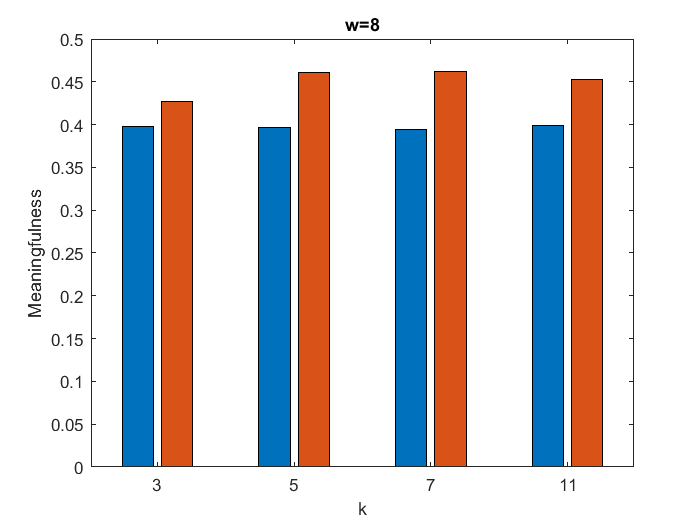

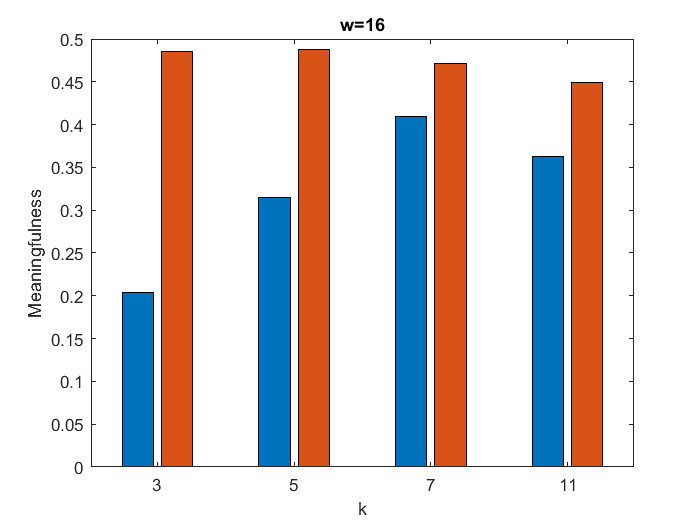

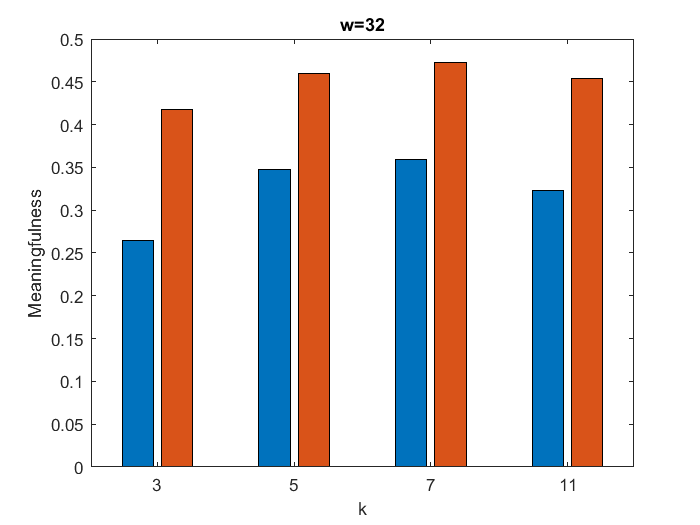


for w = 1:length(ws)
    bar(1:length(ks),meaningfulness_combined(:,:,w))
    set(gca,'XTickLabel',{'3', '5', '7', '11'})
    title("w="+ws(w))
    xlabel('k')
    ylabel('Meaningfulness')
    figure
end